# Discrete decoding

For some applications, for example a typing prosthesis, the details of the kinematics are unimportant. We can use the Bayesian classifier to predict the endpoint of a reach, given the spike counts of a population of neurons. 

clear all; clc;
load spikeCounts.mat %[repetitions, neurons, targets]

This experiment uses the leave-one-out cross-validation method. In this approach, each time a single trial (i.e., the neural data from one repetition for a specific target) is set aside as the test set, while all remaining data are used to train the decoder. The model’s performance is then evaluated on the held-out trial. This process is repeated so that every trial is used once as the test set. In this way, we make full use of all available data and obtain (number of trials × number of targets) independent assessments of decoder performance.

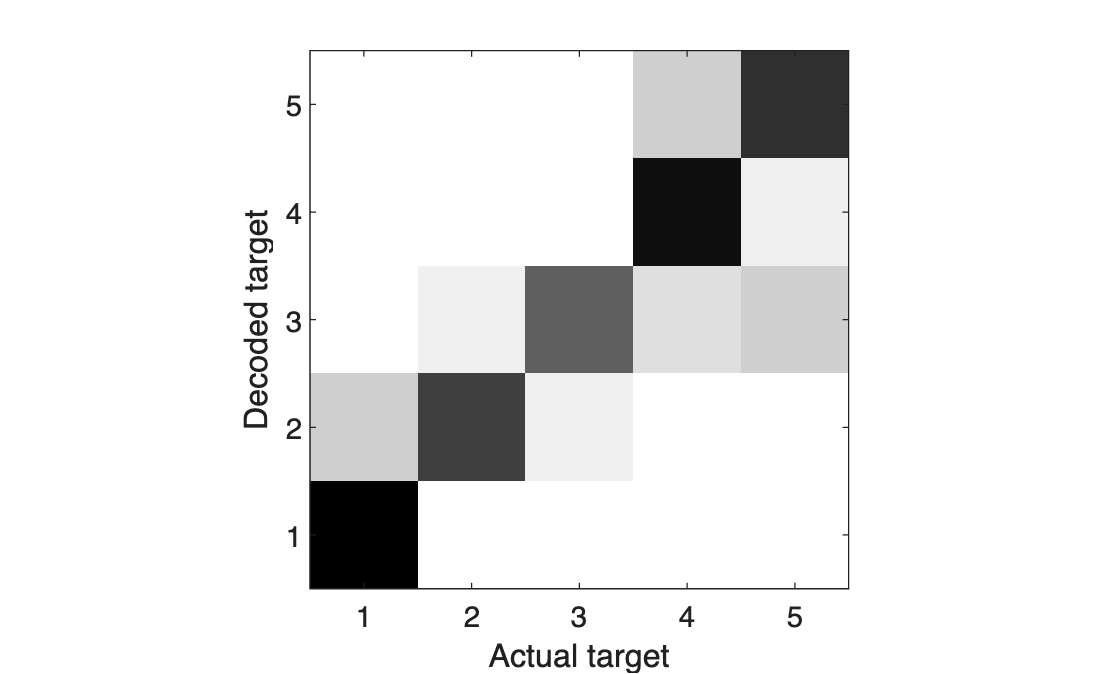

add = squeeze(sum(SpikeCounts,1));
for i = 1:size(SpikeCounts,1)
    for j = 1:size(SpikeCounts,3)
        test_data = SpikeCounts(i,:,j);
        lambda = add / size(SpikeCounts,1);
        lambda(:, j) = (add(:, j) - test_data') / (size(SpikeCounts,1)-1);
        lambda = lambda+eps;
        for k = 1:size(SpikeCounts,3)
            score(k) = sum(test_data .* log(lambda(:,k)') - lambda(:,k)');
        end
        [~, decoded_target] = max(score);
        decoded_results{i,j} = [j, decoded_target];
        Results(j,i).actualTarg = [j];
        Results(j,i).decodedTarg = [decoded_target];
    end
end
results = cell2mat(decoded_results(:));
accuracy = sum(results(:, 1) == results(:, 2)) / size(results,1);

ConfuMat = plotConfusion(Results);